# Examen Parcial Pasado

## Pregunta 2:

De acuerdo con el principio de Arquímedes, la** fuerza de flotación** es igual al** peso del fluido desplazado** por la porción sumergida de un objeto. Para la esfera de corcho ilustrada en la siguiente figura, usa el método de bisección para determinar la altura h de la porción que queda encima del agua. Utiliza los siguientes valores para tu cálculo:** r = 1m**, densidad de la esfera **ρe = 200kg/m3** y densidad del agua **ρa = 1000kg/m3**. Observa que el volumen de la porción de la esfera por encima del agua se puede calcular mediante:


$$V=\frac{\pi h^2 }{3}\left(3r-h\right)$$


***Para estar en equilibrio***, la fuerza de flotación (que depende de h) ***debe ser igual*** al peso total de la esfera. Recuerda que **F=mg** y** m=ρV**. Por lo tanto, **F = ρVg**. ¿Peso de la  esfera? ¿Volumen sumergido (desplazado)? ¿Fuerza de flotación? `En equilibrio la fuerza total es cero.`

- Escribe la función que especifica la fuerza total.

- Grafica esta función dentro de límites adecuados.

-  Elige valores iniciales para la función de bisección.

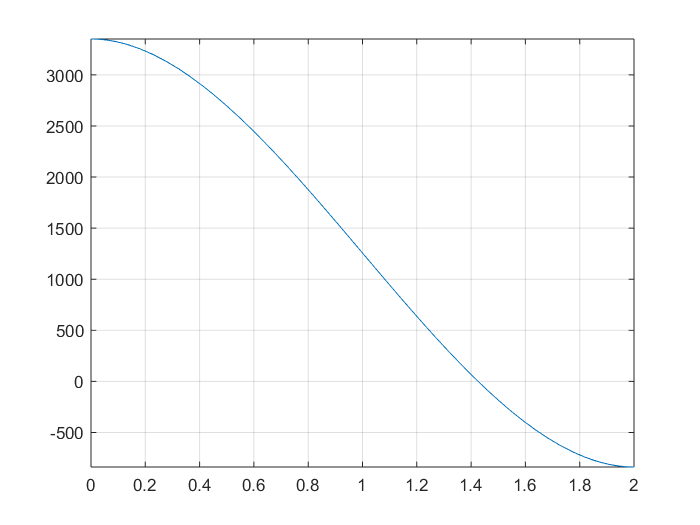

r=1;
pe=200;
g=9.8;
pa=1000;
volEsfera= (4/3)*r^3*pi;
ft = @(h) volEsfera*(pa-pe) - pa*((pi*h.^2).*((3*r-h)/3));
%fflot = @(h) pa.*g.* (vt- ((pi*h.^2)/3.*(3.*r-h)));
a=0;
b=2*r;
fplot(ft,[a,b]);
grid on;

[x,i] = biseccion(ft,1.4,1.6)

x =    1.425718549166519


i =     48
